walk_i = 1

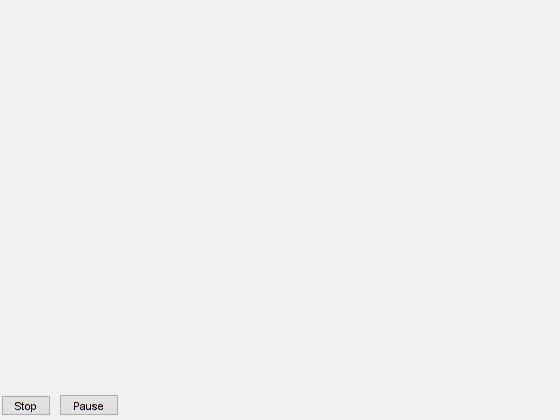

Error using isappdata
Value must be a handle.

Error in callAllOptimPlotFcns (line 97)
    if isappdata(fig,'data')

Error in globaloptim.bmo.BlackboxModelOptimizer/outputAndPlots (

% Optimze WFA parameters for each walk

for walk_i = 1:nWalk
    walk_i 
    paramsT.Variables = paramsTzeros.Variables ; % reset paramsT
    
    % steps per walk
    OSTend_i = rowsData - nstepOST*(nWalk-walk_i) ;
    OSTstart_i = OSTend_i - nstepOST + 1 ;
    ISTend_i    = OSTstart_i - 1 ;
    ISTstart_i  = ISTend_i - nstepIST + 1 ;
    
    
    for cap_i = 1:ncap
        
        cap_i ;
        % symbol under cap_i
        capCateg_i = string(capCateg(cap_i)) ;
        symCapCategT_i = symCapCategT(string(symCapCategT.CapCategory) == capCateg_i,:) ;
        symCapCateg_i = string(symCapCategT_i(:,1).Variables) ;
        
        % create symbol list based on end name price volume
        sym_openprice_i     = transpose(strcat(symCapCateg_i,"_open")) ;
        sym_highprice_i     = transpose(strcat(symCapCateg_i,"_high")) ;
        sym_lowprice_i      = transpose(strcat(symCapCateg_i,"_low")) ;
        sym_closeprice_i    = transpose(strcat(symCapCateg_i,"_close")) ;
        sym_volume_i    = transpose(strcat(symCapCateg_i,"_volume")) ;

        % dataset for walk_i and cap_i
        ISTdataSet_i.openpriceTT    = dataInput.openpriceTT(ISTstart_i:ISTend_i,sym_openprice_i) ;
        ISTdataSet_i.highpriceTT    = dataInput.highpriceTT(ISTstart_i:ISTend_i,sym_highprice_i) ;
        ISTdataSet_i.lowpriceTT     = dataInput.lowpriceTT(ISTstart_i:ISTend_i,sym_lowprice_i) ;
        ISTdataSet_i.closepriceTT   = dataInput.closepriceTT(ISTstart_i:ISTend_i,sym_closeprice_i) ;
        ISTdataSet_i.volumeTT       = dataInput.volumeTT(ISTstart_i:ISTend_i,sym_volume_i) ;
        
        % ISTendDate
        ISTendDate = ISTdataSet_i.openpriceTT.Time(end,:);
        
        % Optimize optimParams per walk
        startOptimPoint = size(ISTdataSet_i.openpriceTT,1) - nstepTrain ; % starting point of IST date
        
        optimParams_walk_i_cap_i = optimParamsFcn (ISTdataSet_i, startOptimPoint, lb, ub) ;
        
        % save optimparams
        paramsT(:,cap_i).Variables = transpose(optimParams_walk_i_cap_i) ;
        
    end

    paramsStruct(walk_i).walk_i = walk_i ;
    ISTdateWalk_i = ISTdataSet_i.volumeTT.Time ;
    paramsStruct(walk_i).ISTenddate_walk_i = ISTdateWalk_i(end) ;
    paramsStruct(walk_i).paramsT = paramsT ;

end